# Correction of the spherical particles

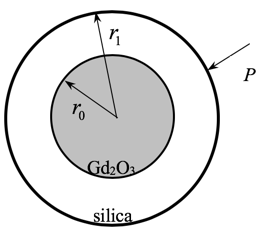

The proposed solution is done using the solving function of Matlab, which means skiping the simplification of the equilibrium equation. The simplification is however shown in part 8 appendix for information.

## 1. Definition of the strain components

We assume that $\overrightarrow{u} =f\left(r\right)$

Consider the point M sent to M', such that $\overrightarrow{\mathrm{MM'}} =\overrightarrow{u}$ 

- $\varepsilon_r$: We take a second point P such that $\overrightarrow{\mathrm{MP}} =\overrightarrow{dr}$ , so along the radial axis, it is sent to P' such that $\overrightarrow{\mathrm{PP'}} =\overrightarrow{dr} +\overrightarrow{du}$ . We have   $\varepsilon_r =\frac{\mathrm{M'P'}-\mathrm{MP}}{\mathrm{MP}}=\frac{\left(dr+u+du-u\right)-dr}{dr}=\frac{du}{dr}$

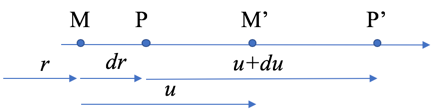

- $\varepsilon_{\theta }$ : We take a third point Q such that $\overrightarrow{\mathrm{MQ}} =r\overrightarrow{d\theta }$ , Q being at the same distance $r$. Therefore $\overrightarrow{\mathrm{M'Q'}} =\left(r+u\right)\overrightarrow{d\theta }$. We have therefore  $\varepsilon_{\theta } =\frac{\mathrm{M'}Q\prime -\mathrm{M}Q}{\mathrm{M}Q}=\frac{\left(r+u\right)d\theta -\mathrm{rd}\theta }{rd\theta }=\frac{u}{r}$

    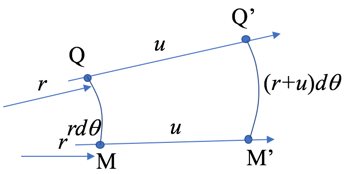

Owing to the symmetry : $\varepsilon_{\varphi } =\varepsilon_{\theta } =u/r$

% proposition de Sylvain (2018)
clear all; 
syms u(r)
eps_r = diff(u, r);
eps_t = u / r;
Eps = [eps_r 0 0; 0 eps_t 0; 0 0 eps_t]

$$Eps(r) = \left(\begin{array}{ccc} \frac{\partial }{\partial r}u\left(r\right) & 0 & 0\\ 0 & \frac{u\left(r\right)}{r} & 0\\ 0 & 0 & \frac{u\left(r\right)}{r} \end{array}\right)$$

## 2. Stress tensor

We recall the Lame' equation : $\sigma^{\sim } =\lambda \mathrm{tr}\left(\varepsilon^{\sim } \right)\tilde{I} +2G\varepsilon^{\sim }$ , with $\lambda =\frac{\nu E}{\left(1-2\nu \right)\left(1+\nu \right)}$  and $G=\frac{E}{2\left(1+\nu \right)}$ . 

Let's calculate the tensor matrix :

syms L G
Sig = L * trace(Eps) * eye(3) + 2*G*Eps;  % stress tensor
x_r=[1;0;0]; x_t=[0;1;0];
s_r=x_r'*Sig*x_r % sigma_r

$$s\_r(r) = 2\,G\,\frac{\partial }{\partial r}u\left(r\right)+L\,\left(\frac{2\,u\left(r\right)}{r}+\frac{\partial }{\partial r}u\left(r\right)\right)$$

s_t=x_t'*Sig*x_t % sigma_t

$$s\_t(r) = L\,\left(\frac{2\,u\left(r\right)}{r}+\frac{\partial }{\partial r}u\left(r\right)\right)+\frac{2\,G\,u\left(r\right)}{r}$$

When conduction the calculation one shall obtain the following expressions :

     $\sigma_r =\lambda \left(\frac{du}{dr}+2\frac{u}{r}\right)+2G\frac{du}{dr}$  and $\sigma_{\theta } =\sigma_{\varphi } =\lambda \left(\frac{du}{dr}+2\frac{u}{r}\right)+2G\frac{u}{r}$ 

## 3-4. Equilibrium equations

The last two equilibrium equations are nil. the first one simplifies to : $\frac{\partial \sigma_r }{\partial r}+\frac{2\left(\sigma_r -\sigma_{\theta } \right)}{r}=0$ 

Solving this equation on Matlab leads to :

eq1 = diff(s_r, r) + 2/r*(s_r-s_t); % = 0
eq1 = simplify(eq1);
usol(r)=dsolve(eq1==0,r)  % resolution of the differential equation

$$usol(r) = \frac{C_{2}}{r^{2}}-\frac{C_{1}\,r}{3\,\left(2\,G+L\right)}$$

eq2 = eq1/(L+2*G);
u2(r)=dsolve(eq2==0,r) % same resolution, but we know that it can devided by (L+2*mu) 

$$u2(r) = \frac{C_{2}}{r^{2}}-\frac{C_{1}\,r}{3}$$

% to simplify the constants

We recopy the two first bloc linking the stresses $\sigma_r(r)$ and $\sigma_t(r)$to the function $u(r)$, after defining this time the displacement function as given above :


$$u(r)=\frac{C_2}{r^2}-\frac{C_1r}{3}$$


clear all
syms C1 C2 r L G 
u(r)=C1*r/3+C2/r^2; % displacement function with constants
eps_r = diff(u, r);  % strains
eps_t = u / r;
Eps = [eps_r 0 0; 0 eps_t 0; 0 0 eps_t];  %strain tensor
Sig = L * trace(Eps) * eye(3) + 2*G*Eps;  % stress tensor
x_r=[1;0;0]; x_t=[0;1;0];
s_r=x_r'*Sig*x_r; % sigma_r
s_t=x_t'*Sig*x_t; % sigma_t

## 5. Boundary conditions

The boundary conditions are mixed a nil displacement and an applied pressure.

In $r=r_0$ the displacement is nil $u\left(r_0 \right)=0$ $u=C_1 \frac{r_0 }{3}+\frac{C_2 }{{r_0 }^2 }=0$ (1)

In $r=r_1$ there is an external force, we can write $\sigma^{\sim } \cdot \overrightarrow{r} =-P\overrightarrow{r}$ where $P$ is the absolute value of the surrounding pressure. Developping the former equation leads to 

$\left\lbrack \begin{array}{c}\sigma_r \left(r_1 \right)\\0\\0\end{array}\right\rbrack =-\left\lbrack \begin{array}{c}P\\0\\0\end{array}\right\rbrack$  $\iff \sigma_r \left(r_1 \right)=-P$ $\iff \frac{C_1 }{3}\left(2G+3L\right)-\frac{4GC_2 }{{r_1 }^3 }=-P$  (2)

(1) and (2) lead to a system of two equations with two unknowns that can be solved leading to:

$C_1 =-\frac{3P{r_1 }^3 }{4G{r_0 }^3 +\left(2G+3\lambda \right){r_1 }^3 }$ and $C_2 =\frac{P{r_0 }^3 {r_1 }^3 }{4G{r_0 }^3 +\left(2G+3\lambda \right){r_1 }^3 }$ 

syms r1 r0 P
e1=u(r0);
e2=s_r(r1)+P;
[A,B]=equationsToMatrix([e1,e2],[C1,C2]);
    mat=inv(A)*B

$$mat = \left(\begin{array}{c} -\frac{3\,P\,{r_{1}}^{3}}{4\,G\,{r_{0}}^{3}+2\,G\,{r_{1}}^{3}+3\,L\,{r_{1}}^{3}}\\ \frac{P\,{r_{0}}^{3}\,{r_{1}}^{3}}{4\,G\,{r_{0}}^{3}+2\,G\,{r_{1}}^{3}+3\,L\,{r_{1}}^{3}} \end{array}\right)$$

C1=mat(1);
C2=mat(2);

## 6. Ploting the results

When not using a computer, it easier to plot the stress as function of the variables $R^{-3}$ since we obtain straight lines.

$\sigma_r =\left(\frac{C_1 }{3}\left(2G+3L\right)\right)-\left(4GC_2 \right)\cdot \frac{1}{r^3 }$    and  $\sigma_{\theta } =\sigma_{\varphi } =\left(\frac{C_1 }{3}\left(2G+3L\right)\right)+\left(2GC_2 \right)\cdot \frac{1}{r^3 }$  

The maximum stress is $\sigma_{\theta } =\sigma_{\varphi }$  , ie. the hoop stress at $r=r_0$.

Using matlab, one can plot the stress assuming a pressure value (the stress components are of course proportional to the pressure.

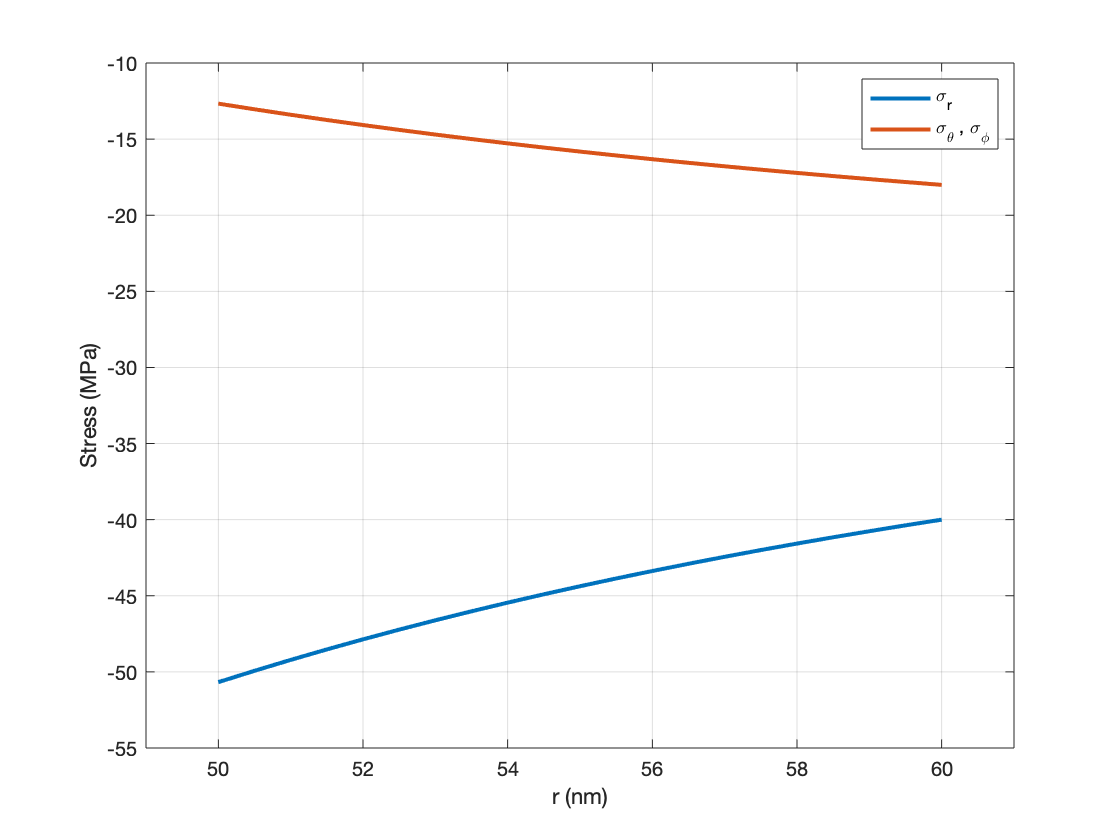

r1=60e-9; r0=50e-9; E=10e9; v=0.2; P=40e6;
L=v*E/(1-2*v)/(1+v); G=E/(2*(1+v)); % Lame constant
r=r0:(r1-r0)/20:r1;
s_r=eval(C1/3*(2*G+3*L)-4*G*C2./r.^3); %numerical calculation of stress
s_t=eval(C1/3*(2*G+3*L)+2*G*C2./r.^3);
plot(r*1e9,s_r/1e6,r*1e9,s_t/1e6,'LineWidth',2)
grid on
xlim([49 61])
%a = get(gca,'XTickLabel');
%set(gca,'XTickLabel',a,'FontName','Helvetica','fontsize',14)
xlabel('r (nm)')
ylabel('Stress (MPa)')
legend('\sigma_r','\sigma_\theta , \sigma_\phi')

sMax=min(s_r)

sMax = -5.0674e+07

## 7.Maximum pressure

The pressure is proportional to the stress so that one can obtain the maximum pressure considering the above numerical value. On the above drawing applying $P=40\;\mathrm{MPa}$  leads to $\sigma_{\mathrm{max}} =-50\ldotp 7$, therefore :


$$\frac{P}{{-\sigma }_{\mathrm{rc}} }=\frac{40}{-50\ldotp 7}\Leftrightarrow P={-\sigma }_{\mathrm{rc}} \frac{40}{-50\ldotp 7}=31.6\,\mathrm{MPa}$$


## 8.appendix

The calculation of the stresses as function of $u$ and $r$ give :

     $\sigma_r =\lambda \left(\frac{du}{dr}+2\frac{u}{r}\right)+2G\frac{du}{dr}$  and $\sigma_{\theta } =\sigma_{\varphi } =\lambda \left(\frac{du}{dr}+2\frac{u}{r}\right)+2G\frac{u}{r}$ 

Replacing in the equilibrium equation and simplifying leads to :


$$\lambda \left(\frac{d^2 u}{dr^2 }+2\frac{1}{r}\frac{\textrm{du}}{\textrm{dr}}-2\frac{u}{r^2 }\right)+2G\frac{d^2 u}{dr^2 }+2G\frac{1}{r}\left(\frac{\textrm{du}}{\textrm{dr}}-\frac{u}{r}\right)=0$$
 
$$\Leftrightarrow \left(\lambda +2G\right)\left(\frac{d^2 u}{dr^2 }+\frac{2}{r}\frac{\textrm{du}}{\textrm{dr}}-2\frac{u}{r^2 }\right)=0$$
 
$$\Leftrightarrow \frac{d^2 u}{dr^2 }+\frac{2}{r}\frac{\textrm{du}}{\textrm{dr}}-\frac{2u}{r^2 }=0$$
 
$$\Leftrightarrow \frac{d}{\textrm{dr}}\left(\frac{\textrm{du}}{\textrm{dr}}+\frac{2u}{r}\right)=0$$
 
$$\Leftrightarrow \frac{d}{\textrm{dr}}\left(\frac{1}{r^2 }\frac{d\left(r^2 u\right)}{\textrm{dr}}\right)=0$$


Then the integration process is :


$$\frac{d}{dr}\left(\frac{1}{r^2 }\frac{d\left(r^2 u\right)}{\mathrm{dr}}\right)=0$$
 
$$\iff \left(\frac{1}{r^2 }\frac{d\left(r^2 u\right)}{\mathrm{dr}}\right)=C_1$$
 
$$\iff \frac{d\left(r^2 u\right)}{\mathrm{dr}}=C_1r^2$$
 
$$\iff r^2u=C_1r^3+C_2$$
 
$$\iff u(r)=C_1r+\frac{C2}{r^2}$$
